## Dynamic Simulation

A step response is a common evaluation of the dynamics of a simulated system. A linear time invariant (LTI) system can be described equivalently as a transfer function, a state space model, or solved numerically with and ODE integrator. This tutorial shows how to simulate a first and second order system in Matlab.

### **First Order System Simulation**

Consider a first order differential equation with constants $K_p=3$ and $\tau_p=2$, input $u$, and output response $y$.

Kp = 3;
taup = 2;


$$\tau_p \frac{dy}{dt} = -y + K_p u$$


Three methods to represent this differential equation is as a (1) transfer function, (2) state space model, and (3) semi-explicit differential equation. Source code is included below to simulate a step response in these three forms.

**1. Transfer Function**


$$\frac{Y(s)}{U(s)} = \frac{K_p}{\tau_p \,s + 1}$$


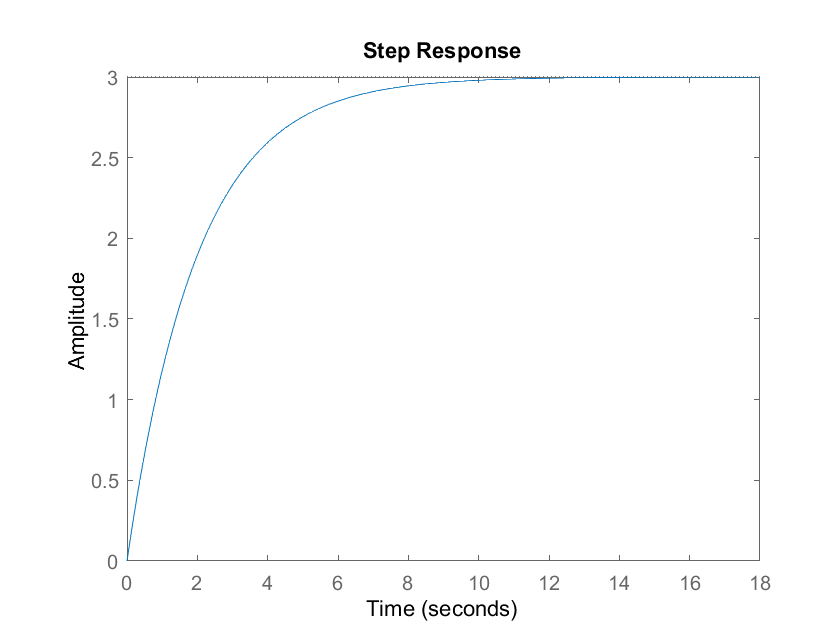

num = [Kp];
den = [taup,1];
[A,B,C,D]=tf2ss(num, den);
sys = ss(A,B,C,D);
step(sys)

**2. State Space Model**


$$\dot x = A x + B u$$



$$y = C x + D u$$



$$A = -\frac{1}{\tau_p} \quad B = \frac{K_p}{\tau_p} \quad C=1 \quad D=0$$


A = -1/taup;
B = Kp/taup;
C = 1;
D = 0;
sys = ss(A,B,C,D);
step(sys)

**3. Differential Equation**


$$\frac{dy}{dt} = -\frac{1}{\tau_p} y + \frac{K_p}{\tau_p} u$$


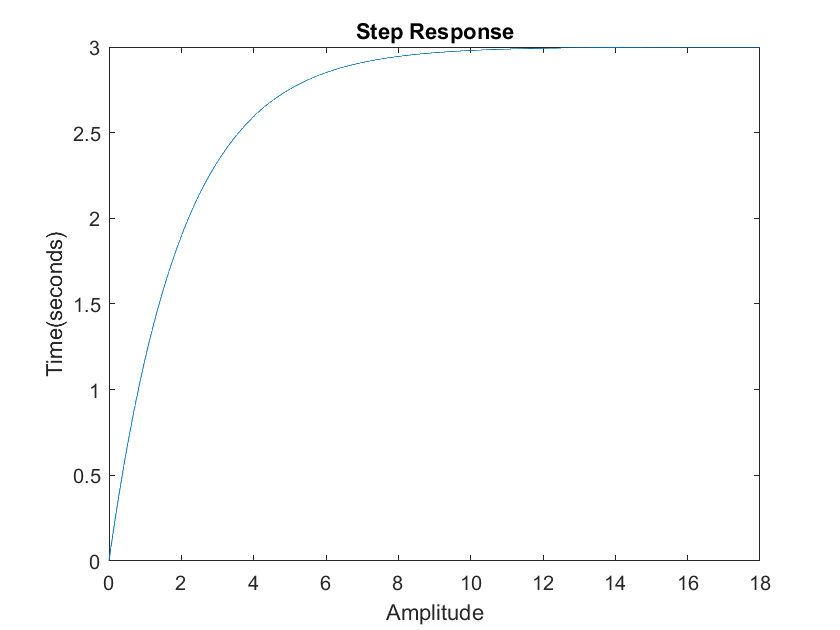

func = @(t,y)(-y+Kp*1)/taup;
[t,y] = ode45(func, linspace(0,18,1000),0);
plot(t,y)
xlabel('Amplitude')
ylabel('Time(seconds)')
title('Step Response')

### **Second Order System Simulation**

Kp = 2.0;
tau = 1.0;
zeta = 0.25;
theta = 0.0;

**1. Laplace Domain, Transfer Functio**n


$$\frac{Y(s)}{U(s)} = \frac{K_p}{\tau_s^2 s^2 + 2 \zeta \tau_s s + 1}e^{-\theta_p s}$$


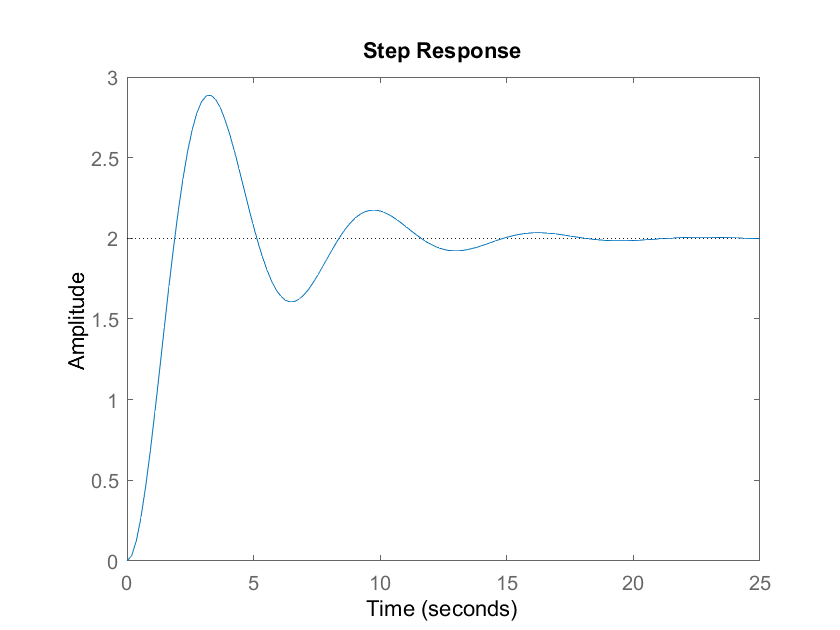

num = [Kp];
den = [tau^2,2*zeta*tau,1];
[A,B,C,D]=tf2ss(num, den);
sys = ss(A,B,C,D);
step(sys)

**2. State Space Form**


$$\left[ \matrix{\dot x_1\cr \dot x_2}\right] = \left[ \matrix{0&1\cr -\frac{1}{\tau_s^2}&-\frac{2 \zeta}{\tau_s}}\right] \left[ \matrix{x_1\cr x_2}\right] + \left[ \matrix{0 \cr \frac{K_p}{\tau_{s}^2}}\right] u\left(t-\theta_p\right)$$



$$y = \left[ \matrix{1 & 0}\right] \left[ \matrix{x_1 \cr x_2}\right] +\left[ \matrix{0}\right] u$$


A = [0,1;-1/tau^2,-2*zeta/tau];
B = [0;Kp/tau^2];
C = [1,0];
D = 0;
sys = ss(A,B,C,D);
step(sys)

**3. Second Order Differential Equation**


$$\tau_s^2 \frac{d^2y}{dt^2} + 2 \zeta \tau_s \frac{dy}{dt} + y = K_p \, u\left(t-\theta_p \right)$$


[t,y] = ode45(@ode2, linspace(0,25,1000),[0;0]);
y = y(:,1)

y =          0
    0.0006
    0.0025
    0.0056
    0.0098
    0.0153
    0.0220
    0.0297
    0.0386
    0.0487


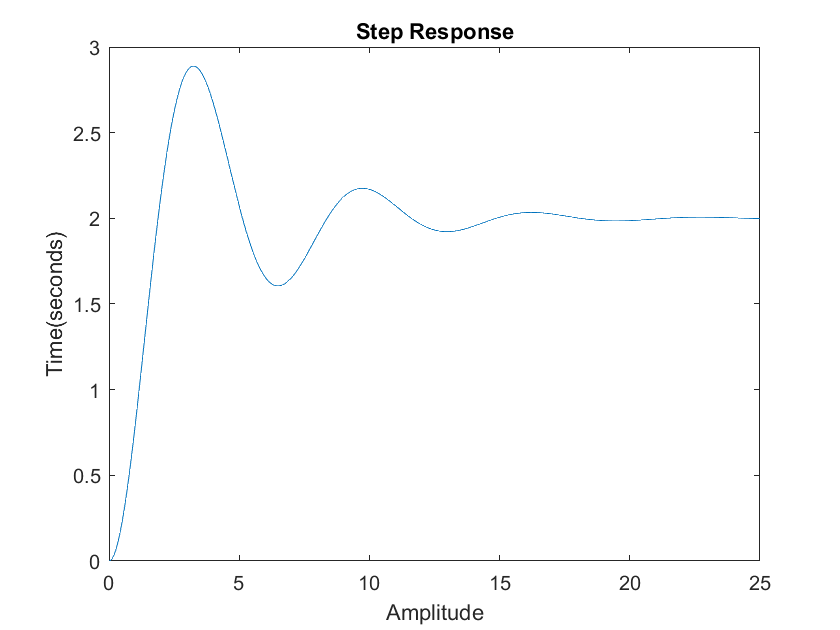

plot(t,y)
xlabel('Amplitude')
ylabel('Time(seconds)')
title('Step Response')

function dYdt = ode2(t,Y)
y = Y(1);
dydt = Y(2);
Kp = 2.0;
tau = 1.0;
zeta = 0.25;
theta = 0.0;
dYdt = [dydt; (-2.0*zeta*tau*dydt - y + Kp)/tau^2];
end

### **Higher Order Simulation**

A simple higher order simulation is the combination of *n* first order equations. The value of the time constant is $10/n$ in this example. The first equation is a first order differential expression.


$$\tau \frac{dy_1}{dt} = -y_1 + 1$$


Additional equations are also first order differential expressions for $i = 2, n$.


$$\tau \frac{dy_i}{dt} = -y_i + y_{i-1}$$
